cd 'C:\Users\natha\Desktop\BMEN E3920\data_human_Bone\skull_absent'

%read in nail image
noskull_img = load("imgData_CData_500.mat");
I0 = noskull_img.ImageData_filtered;

cd 'C:\Users\natha\Desktop\BMEN E3920\data_human_Bone\skull_present'

%read in skull image
skull_img = load("imgData_CData_500.mat");
I1 = skull_img.ImageData_filtered;



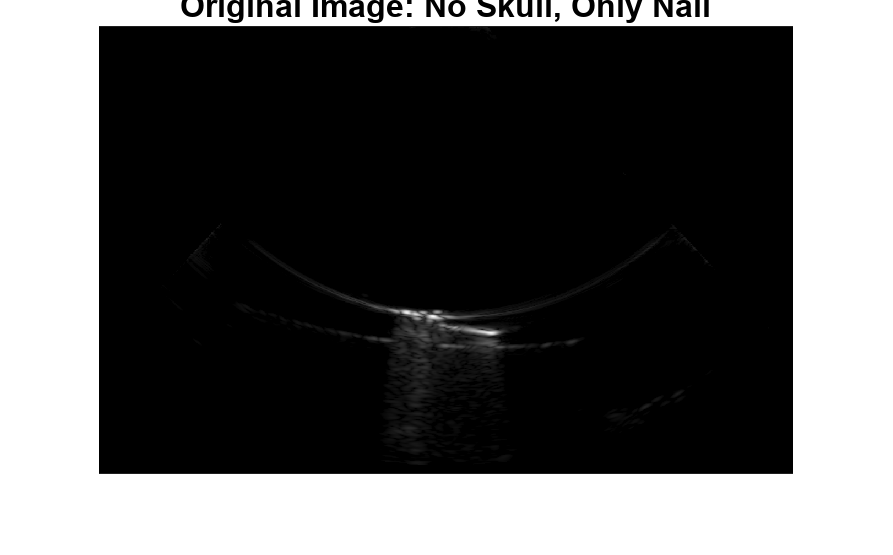

% Grayscale normalization

I0 = uint8(255*mat2gray(I0));
imshow(I0);
title('Original Image: No Skull, Only Nail')

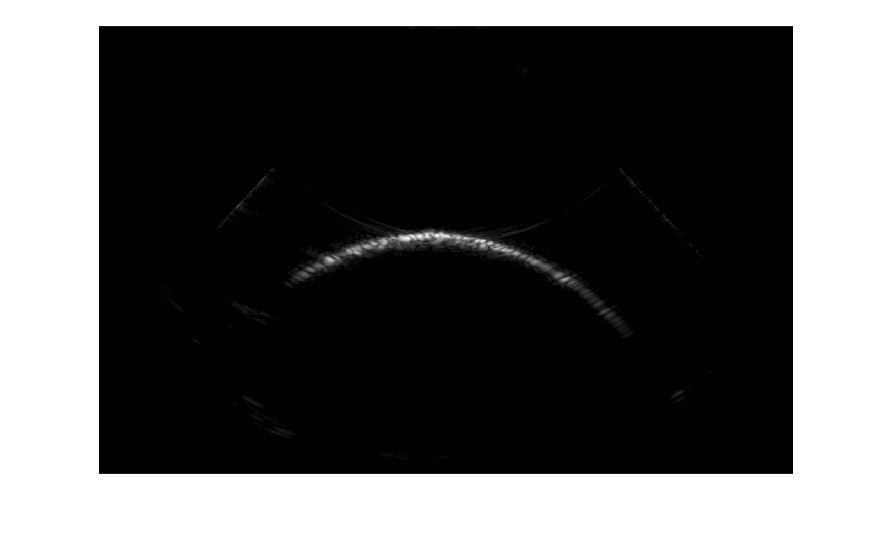


I1 = uint8(255*mat2gray(I1));
imshow(I1);


%dynamic mask creation f0r I0
% Find the maximum value in the matrix and its index for I0
[maxValue, maxIndex] = max(I0(:));

% Convert the index to row and column subscripts
[row, col] = ind2sub(size(I0), maxIndex)

row = 527

col = 606


%create the mask
mask_I0 = zeros(size(I0))

mask_I0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0   


% Define the center point
center_point0 = [row,col]

center_point0 =    527   606


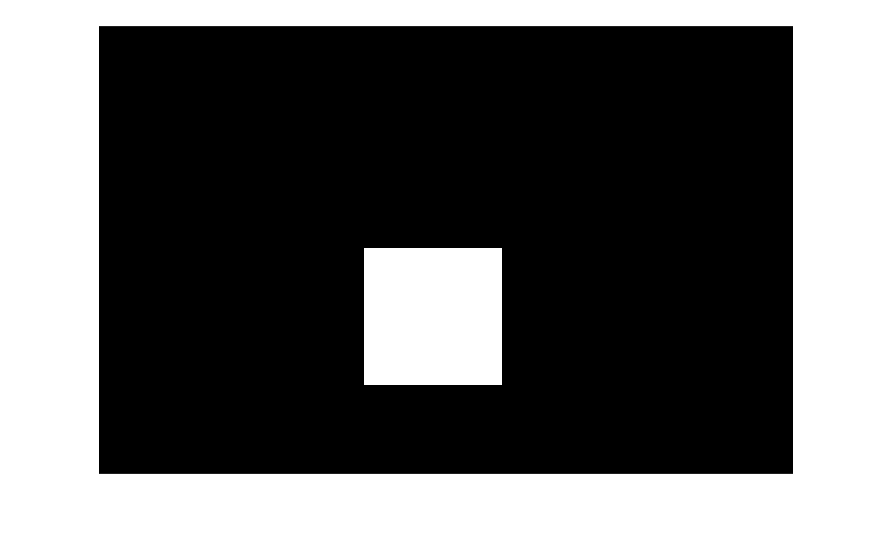


% Define the size of the square
square_size = 250;

% Calculate the indices of the square in the matrix
row_indices = center_point0(1) - floor(square_size/2) + 1 : center_point0(1) + floor(square_size/2);
col_indices = center_point0(2) - floor(square_size/2) + 1 : center_point0(2) + floor(square_size/2);

% Assign the value of 1 to the square in the matrix
mask_I0(row_indices, col_indices) = 255;

imshow(mask_I0)




%dynamic mask creation f0r I1
% Find the maximum value in the matrix and its index for I0
[maxValue, maxIndex] = max(I1(:));

% Convert the index to row and column subscripts
[row, col] = ind2sub(size(I1), maxIndex)

row = 380

col = 614


%create the mask
mask_I1 = zeros(size(I1))

mask_I1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0   


% Define the center point
center_point1 = [row,col]

center_point1 =    380   614


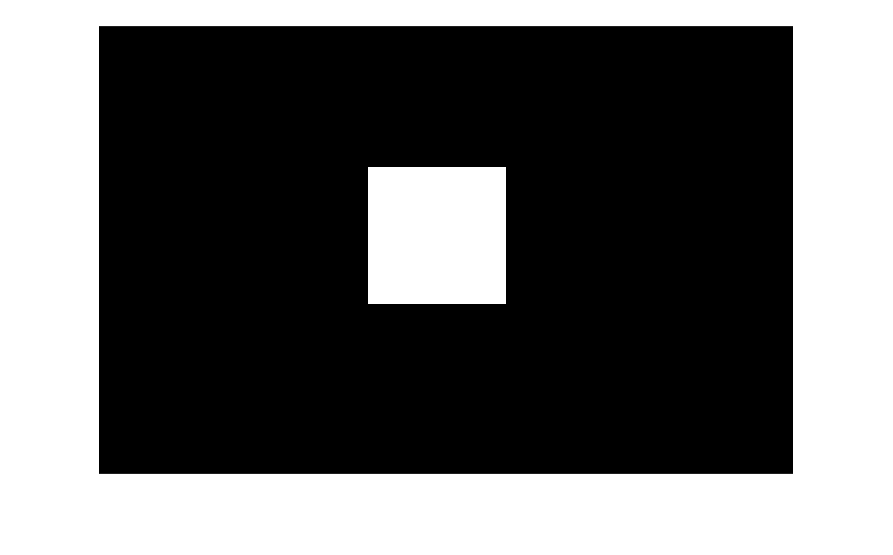


% Define the size of the square
square_size = 250;

% Calculate the indices of the square in the matrix
row_indices = center_point1(1) - floor(square_size/2) + 1 : center_point1(1) + floor(square_size/2);
col_indices = center_point1(2) - floor(square_size/2) + 1 : center_point1(2) + floor(square_size/2);

% Assign the value of 1 to the square in the matrix
mask_I1(row_indices, col_indices) = 255;

imshow(mask_I1)

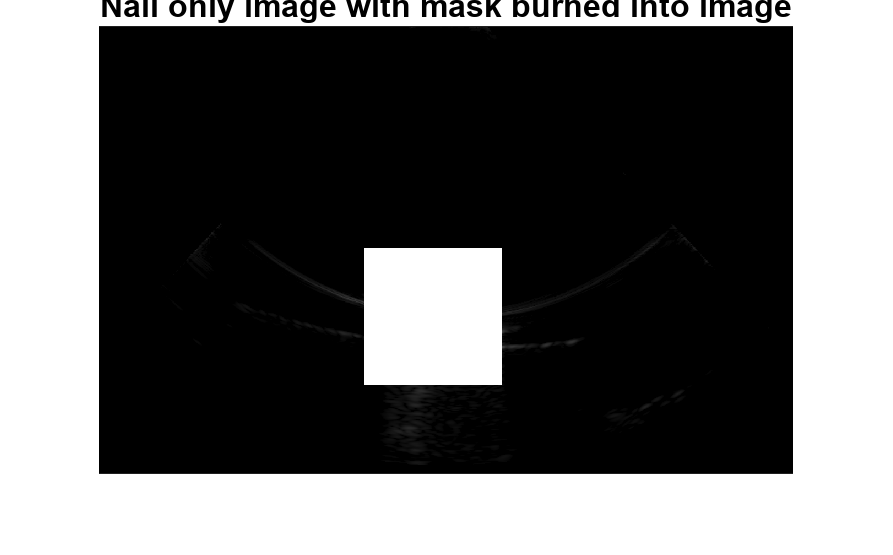








% Multiply image by mask

    % displays mask over original image 
    I0_b1 = I0;
    I0_b1(mask_I0>0) = 255;
    imshow(I0_b1);
    title('Nail only image with mask burned into image')

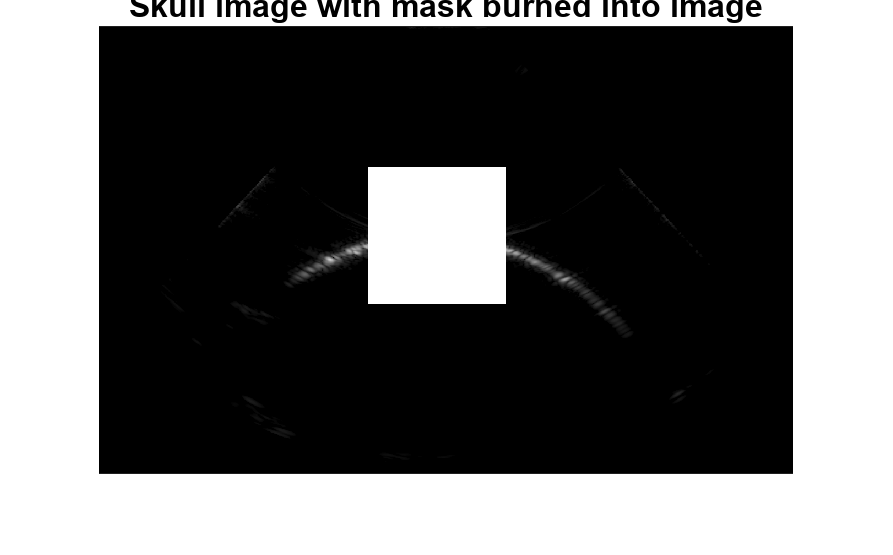

    
    I1_b1 = I1;
    I1_b1(mask_I1>0) = 255;
    imshow(I1_b1);
    title('Skull image with mask burned into image')

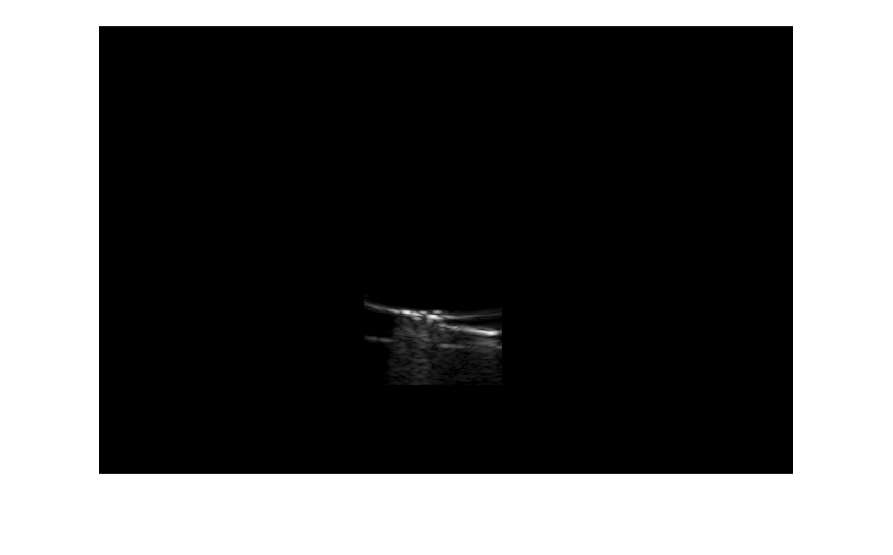

    
    % displays masked image and blacks out everywhere else
    I0_b2 = I0;
    I0_b2(~mask_I0) = 0;
    imshow(I0_b2);

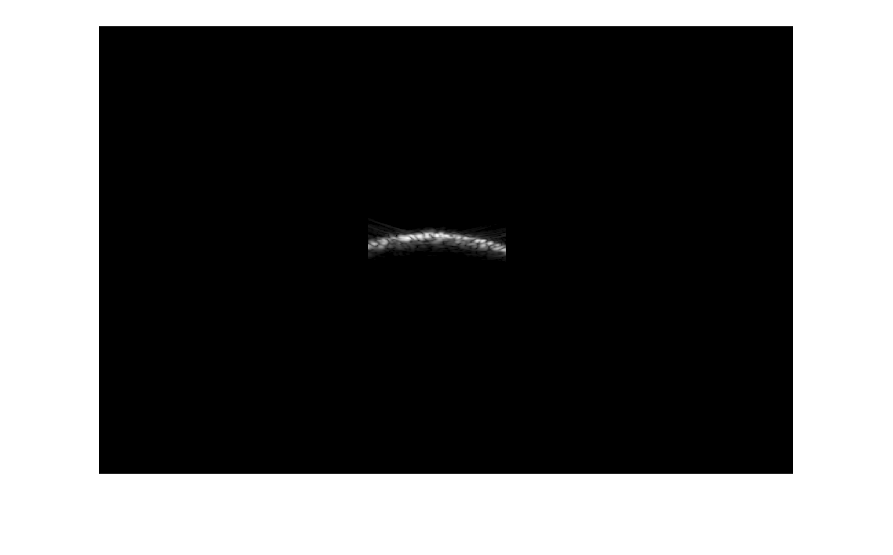

    
    I1_b2 = I1;
    I1_b2(~mask_I1) = 0;
    imshow(I1_b2);


% crop image
tl_crop_image0 = center_point0 - square_size/2

tl_crop_image0 =    402   481


I0_RoI = imcrop(I0_b2, [tl_crop_image0(2) tl_crop_image0(1) square_size square_size])

I0_RoI = 251×251 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

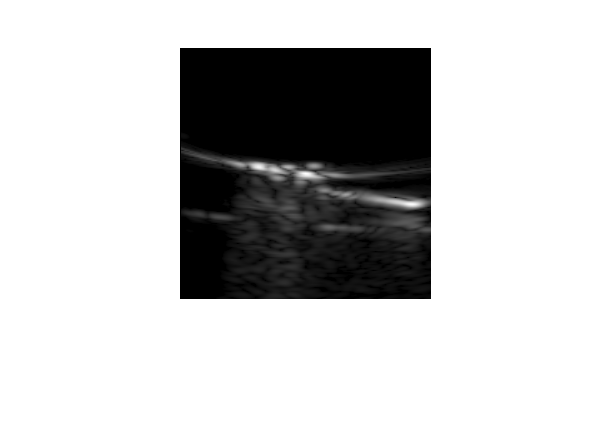

imshow(I0_RoI);



tl_crop_image1 = center_point1 - square_size/2

tl_crop_image1 =    255   489


I1_RoI = imcrop(I1_b2, [tl_crop_image1(2) tl_crop_image1(1) square_size square_size])

I1_RoI = 251×251 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

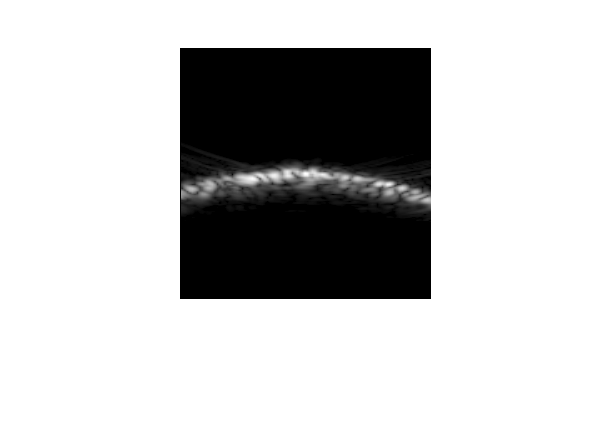

imshow(I1_RoI);


% Take average of the ROI
P = mean(I0_RoI(:));
P_0 = mean(I1_RoI(:));

% Determine attenuation
attenuation = (1 - P/P_0) * 100

attenuation = -36.4428

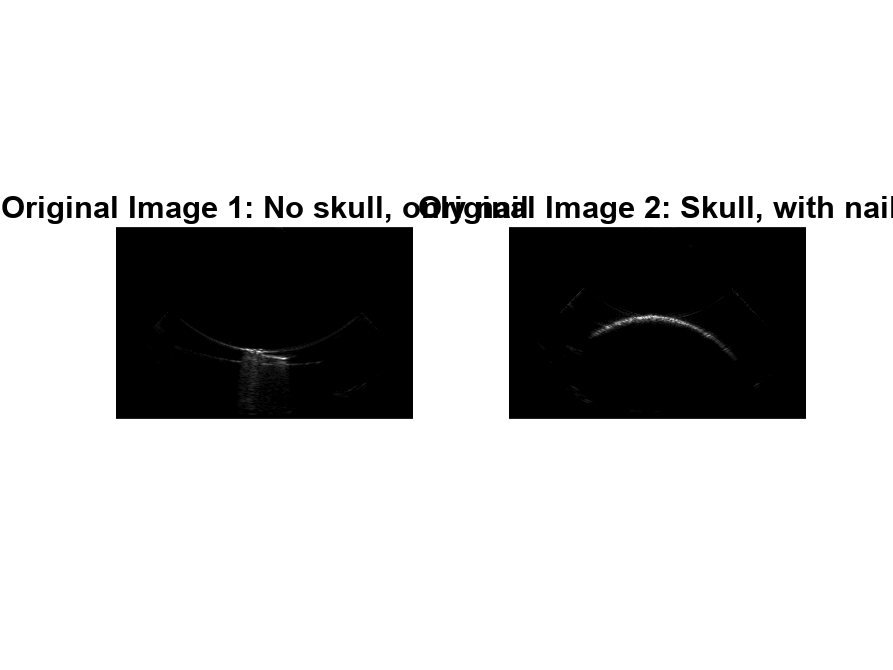

% Figure maker

figure
subplot(1,2,1)
imshow(I0)
title('Original Image 1: No skull, only nail')

subplot(1,2,2)
imshow(I1)
title('Original Image 2: Skull, with nail')

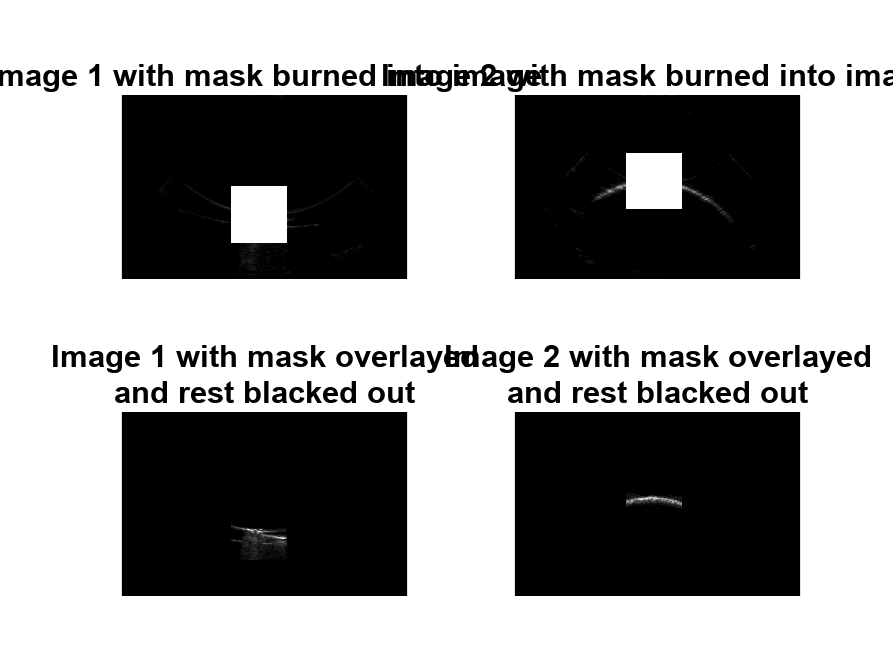

%Mask overlay on images, with rest blacked out
figure
subplot(2,2,1)
imshow(I0_b1)
title('Image 1 with mask burned into image')

subplot(2,2,3)
imshow(I0_b2)
title({'Image 1 with mask overlayed', 'and rest blacked out'})

subplot(2,2,2)
imshow(I1_b1)
title('Image 2 with mask burned into image')

subplot(2,2,4)
imshow(I1_b2)
title({'Image 2 with mask overlayed','and rest blacked out'})

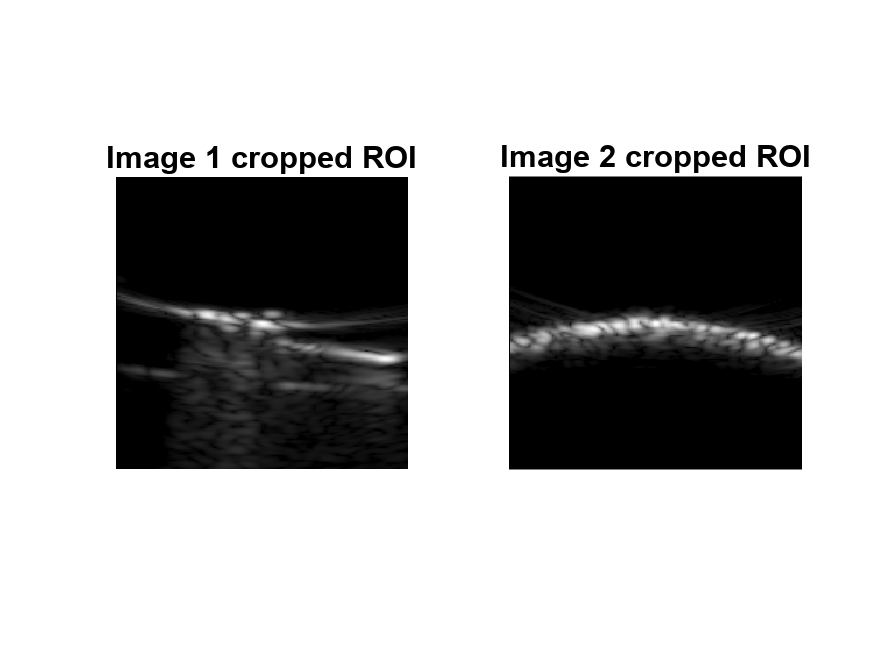

figure
subplot(1,2,1)
imshow(I0_RoI)
title('Image 1 cropped ROI')

subplot(1,2,2)
imshow(I1_RoI)
title('Image 2 cropped ROI')

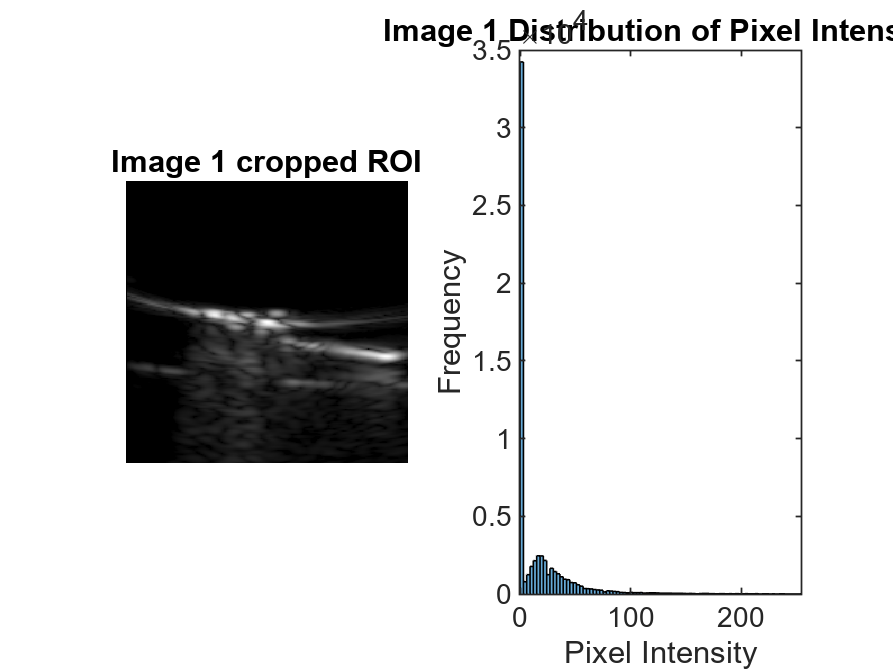

figure
subplot(1,2,1)
imshow(I0_RoI)
title('Image 1 cropped ROI')

subplot(1,2,2)
histogram(I0_RoI)
xlim([-1 255])
title('Image 1 Distribution of Pixel Intensity')
xlabel('Pixel Intensity')
ylabel('Frequency')

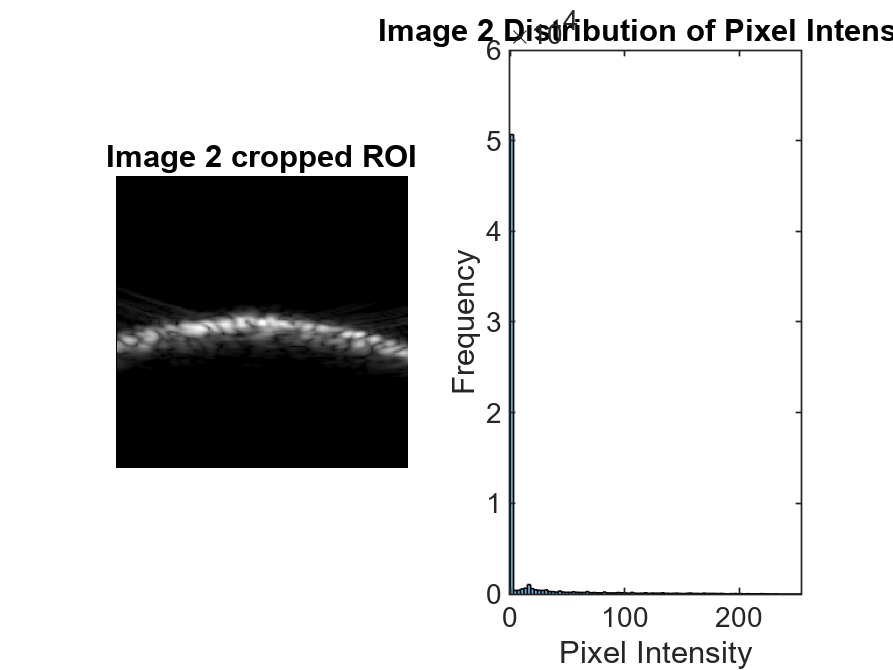

figure
subplot(1,2,1)
imshow(I1_RoI)
title('Image 2 cropped ROI')

subplot(1,2,2)
histogram(I1_RoI)
xlim([-1 255])
title('Image 2 Distribution of Pixel Intensity')
xlabel('Pixel Intensity')
ylabel('Frequency')